# Wave Equation

A general partial differential equation in the PDE toolbox form is 


$$ m\frac{\partial^2 u}{\partial t^2} + d\frac{\partial u}{\partial t} -\mathop{div}(c\nabla u) + au = f.$$


A wave equation in the toolbox form is


$$ m\frac{\partial^2 u}{\partial t^2} -\mathop{div}(c\nabla u) = f,$$


where $d=0, a=0.$

#### Create the geometry $\Omega$ (The **flag** of **Switzerland**)

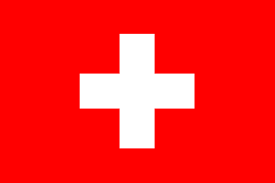

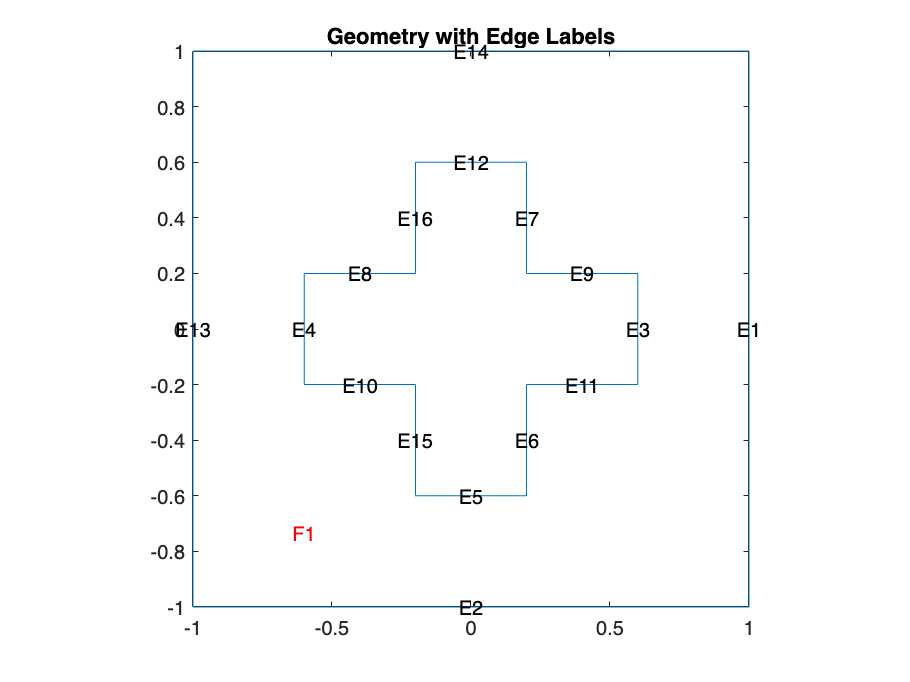

rect1 = [[3; 4]; [-2.5; 2.5; 2.5; -2.5; 2.5; 2.5; -2.5; -2.5]/2.5];
rect2 = [[3; 4]; [-.5; .5; .5; -.5; .5; .5; -.5; -.5;]/2.5];
rect3 = [[3; 4]; [-.5; .5; .5; -.5; 1.5; 1.5; -1.5; -1.5]/2.5];
rect4 = [[3; 4]; [-.5; .5; .5; -.5; -.5; -.5; -1.5; -1.5]/2.5];
rect5 = [[3; 4]; [.5; 1.5; 1.5; .5; .5; .5; -.5; -.5]/2.5];
rect6 = [[3; 4]; [-1.5; -.5; -.5; -1.5; .5; .5; -.5; -.5]/2.5];
gd = [rect1,rect2,rect3,rect4,rect5,rect6];
sf = 'rect1 - rect2 - rect3 - rect4 - rect5 - rect6';
ns = char('rect1','rect2','rect3','rect4','rect5','rect6')';
g = decsg(gd,sf,ns);
pdegplot(g,'EdgeLabels','on','FaceLabels','on') 
xlim([-1.2,1.2]);
axis equal
title 'Geometry with Edge Labels';

#### Problem statement

Solve the solution to the following wave equation:


$$ \frac{\partial^2 u}{\partial t^2} -\mathop{div}(\nabla u) = 0,$$


on the flag of Switzerland $\Omega$, with the mixed conditions on the boundary $\partial \Omega$. 

- To solve the linear wave equation using the programmatic workflow, first create a PDE model.

numberOfPDE = 1;
model = createpde(numberOfPDE);

         2. Include the geometry in the model.

geometryFromEdges(model,g);

         3. Specify the coefficients.

m = 1;
d = 0;
c = 1;
a = 0; 
f = 0; 
specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',f);

         4. Specify the boundary conditions.

applyBoundaryCondition(model,'dirichlet','Edge',[1],'u',0); 
applyBoundaryCondition(model,'neumann','Edge',2:model.Geometry.NumEdges,'g',0);

       5. Set the initial  conditions     

u0 = @(location) atan(cos(pi/2*location.x));
ut0 = @(location) 3*sin(pi*location.x).*exp(sin(pi/2*location.y)); 
setInitialConditions(model,u0,ut0);

       6. Generate a mesh 

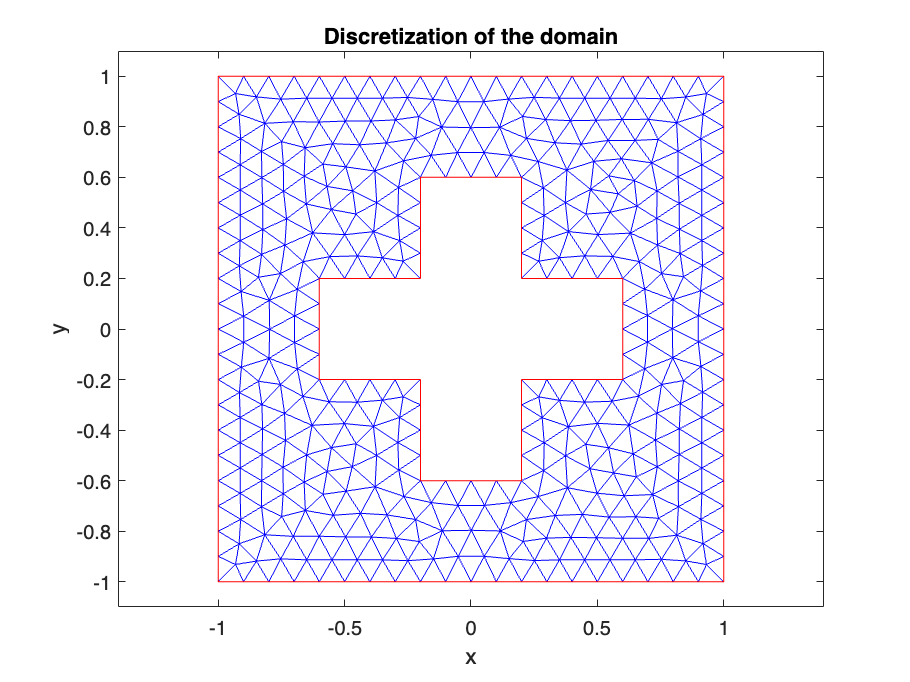

generateMesh(model,'Hmax',0.1); 
figure;
pdemesh(model); 
ylim([-1.1 1.1]); 
axis equal
xlabel x
ylabel y
title 'Discretization of the domain'

       7. Solve the heat equation.

n = 300;
tlist = linspace(0,30,n);
model.SolverOptions.ReportStatistics ='on';
result = solvepde(model,tlist);

11615 successful steps
1406 failed attempts
26005 function evaluations
1 partial derivatives
3387 LU decompositions
26004 solutions of linear systems


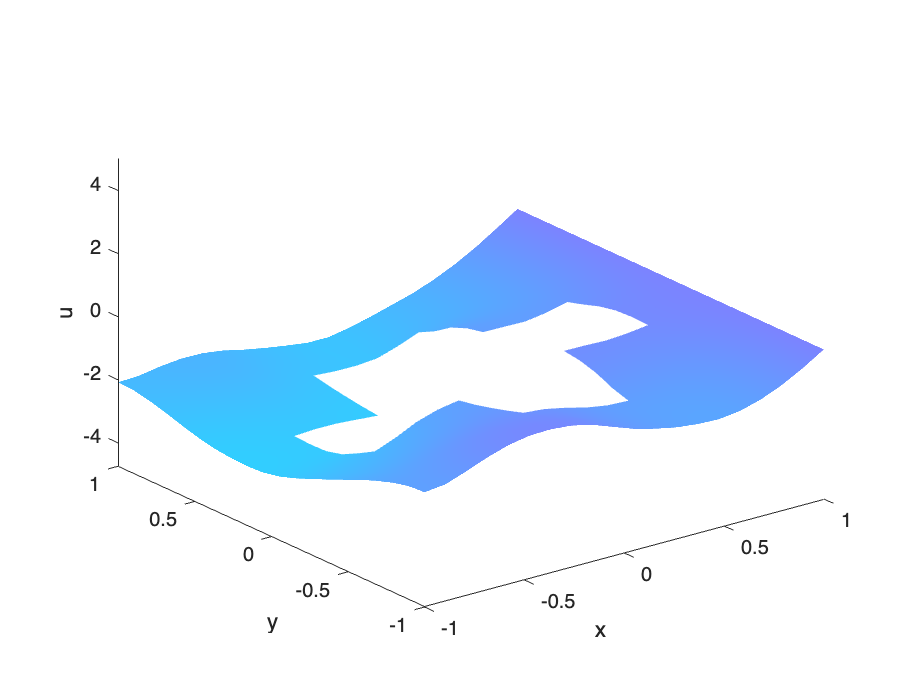

u = result.NodalSolution;
figure
umax = max(max(u)); umin = min(min(u)); 
for i = 1:n
pdeplot(model,'XYData',u(:,i),'ZData',u(:,i),'ZStyle','continuous','Mesh','off','XYGrid','on','ColorBar','off');
axis([-1 1 -1 1 umin umax]); caxis([umin umax]);
xlabel x
ylabel y
zlabel u
M(i) = getframe;
end

Exercise: Try to create the flag of Japan and then repeat the experiment.

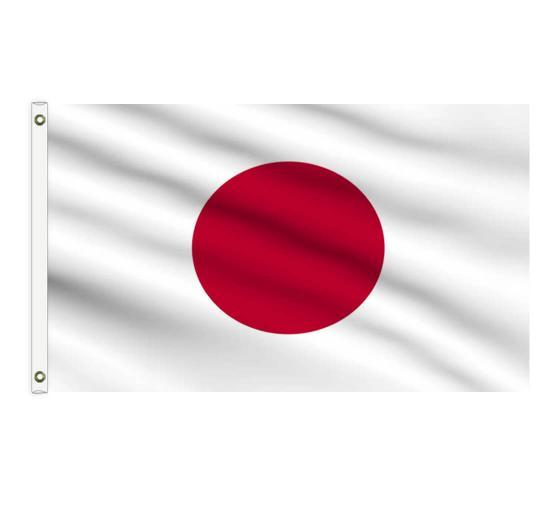

Reference: *Partial Differential Equation ToolboxTM User's Guide *